%Punto 3
%3. Sea el sistema constituido por el subsistema G1 = K/(s^2+2s+26) y G2 = 1/(s+7) en realimentación negativa.

syms K s;
G1 = K/(s^2+2*s+26);
G2 = 1/(s+7);

real_neg = simplify(G1/(1+G1*G2));     
K = 177;
real_neg_K = eval(real_neg);
[n, d]=numden(real_neg_K);

Fdt_real_neg=tf(sym2poly(n),sym2poly(d))


Fdt_real_neg =
 
        177 s + 1239
  ------------------------
  s^3 + 9 s^2 + 40 s + 359
 
Continuous-time transfer function.



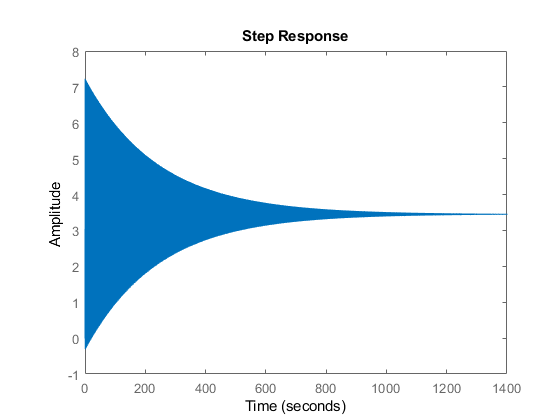

%a) Simular la respuesta ante escalón y rampa para diferentes valores de K.
%escalón
step(Fdt_real_neg);

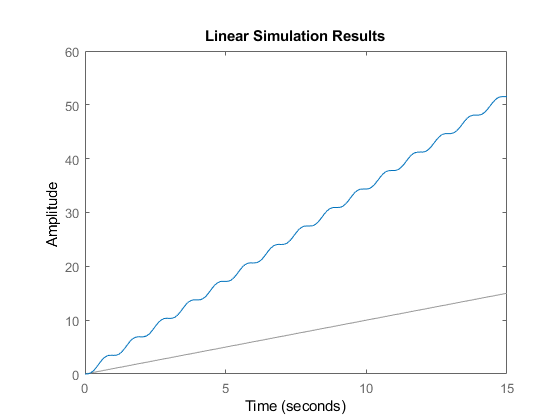


% rampa
Tfinal = 15; %segundos que dura la simulacion
t = 0:.1:Tfinal;

rampa = t;
lsim(Fdt_real_neg,rampa,t);




%b) Intentar determinar el margen de estabilidad.
clear;
syms s K
G1 = K/(s^2+2*s+26);
G2 = 1/(s+7);

chareq = 1+G1*G2==0

$$chareq = \frac{K}{\left(s+7\right)\,\left(s^{2}+2\,s+26\right)}+1=0$$

cheq = expand(simplify(chareq)) %Ayuda para determinar an

$$cheq = s^{2}+2\,s\neq -26\wedge s\neq -7\wedge s^{3}+9\,s^{2}+40\,s+K+182=0$$

RT=[1 40;
    9 182+K];
b1 = (RT(2,1)*RT(1,2)-RT(1,1)*RT(2,2))/RT(2,1);
b2 = (RT(2,1)*0-RT(1,1)*0)/RT(2,1);
c1 = (b1*RT(2,2)-RT(2,1)*b2)/b1;
c2 = (b1*0-RT(2,1)*0)/b1;
RT = [1 40;
      9 182+K;
      simplify(b1) b2;
      simplify(c1) c2]

$$RT = \left(\begin{array}{cc} 1 & 40\\ 9 & K+182\\ \frac{178}{9}-\frac{K}{9} & 0\\ K+182 & 0 \end{array}\right)$$

K1 = vpasolve(b1, K)

$$K1 = 178.0$$

K2 = vpasolve(c1, K)

$$K2 = -182.0$$

%La función es estable para K=(-182,178)
